clear
clc

table = readtable("iFood6_CNN_history_Aug.csv");
epochs = length(table.loss);

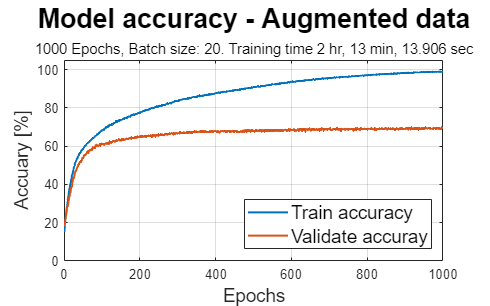

f = figure(1);
f.Position = [0,0,800,500];
plot([table.accuracy,table.val_accuracy].*100,'LineWidth',1.5);
title("Model accuracy - Augmented data","FontSize",20);
subtitle(["1000 Epochs, Batch size: 20. Training time 2 hr, 13 min, 13.906 sec"])
xlabel("Epochs",'FontSize',14);
ylabel("Accuary [%]",'FontSize',14);
xlim([0 1000]);
ylim([0 105]);
grid on
legend('Train accuracy','Validate accuray','Location','southeast','FontSize',14)
saveas(1,"Model accuracy Aug.png");

% Find local minima
lclMin = islocalmin(table.val_loss,"MaxNumExtrema",1);
f = figure(2);
f.Position = [0,0,800,500];
plot([table.loss,table.val_loss],'LineWidth',1.5);
title("Model losses - Augmented data","FontSize",20);
subtitle(["1000 Epochs, Batch size: 20. Training time 2 hr, 13 min, 13.906 sec"])
xlabel("Epochs",'FontSize',14);
ylabel("Loss",'FontSize',14);
xlim([0 1000]);
ylim([-1 17]);
grid on
fitline = find(lclMin==1,1)

fitline = 538

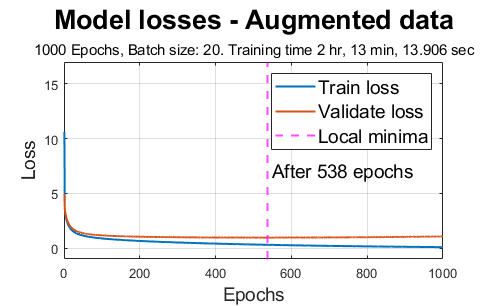

xline(fitline,'m--','LineWidth',1.5)
text(fitline+10,7,'After 538 epochs','FontSize',14)
legend('Train loss','Validate loss','Local minima','Location','northeast','FontSize',14)
saveas(2,"Model losses Aug.png");